# TP 2 Problèmes hyperboliques & Volumes finis

## Programme 1, 

## Question c)

x1 = 0;
x2 = 10;

t0 = 0;
t1 = 2;

a = 1;

c = 0.3;
m = 100;

h = 1/m;
x_grid = x1:h:x2;
dt = c*h/a;
nx = length(x_grid); 
ny = length(t0:dt:t1);

### **Solution initiale**

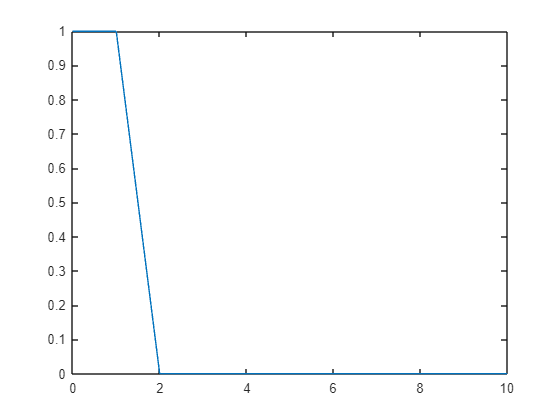

Un = arrayfun(@U0,x_grid);
plot(x_grid, arrayfun(@U0,x_grid))

### Solution numérique :

On va avoir : U(n+1,j) = U(n,j) - (dt/h)*a(n,j)*(U(n,j) - U(n,j-1))

avec a(n,j) = 1/2*(U(n,j) + U(n,j-1)) := sol_moy

for i = 1:ny
    a = 1/2*(Un(1) + 1);
    Un1(1) = Un(1) - dt/h*a*(Un(1) - 1);
    for j = 2:nx
        a = 1/2*(Un(j) + Un(j-1));
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_a = Un 

sol_a =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


avec a(n,j) = U(n,j-1) := sol_retro


Un1 = zeros(1,nx);
Un = arrayfun(@U0,x_grid); 

for i = 1:ny
    a = 1;
    Un1(1) = Un(1) - dt/h*a*(Un(1) -1);
    for j = 2:nx
        a = Un(j-1);
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_b = Un

sol_b =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


avec a(n,j) = U(n,j) := sol_prez


Un1 = zeros(1,nx);
Un = arrayfun(@U0,x_grid); 

for i = 1:ny
    a = Un(1);
    Un1(1) = Un(1) - dt/h*a*(Un(1) - 1);
    for j = 2:nx
        a = Un(j);
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_c = Un

sol_c =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


## Solutions exactes : 

Us1 = arrayfun(@U02, mod(x_grid - a*ny*dt - x1,x2 - x1) + x1)

Us1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


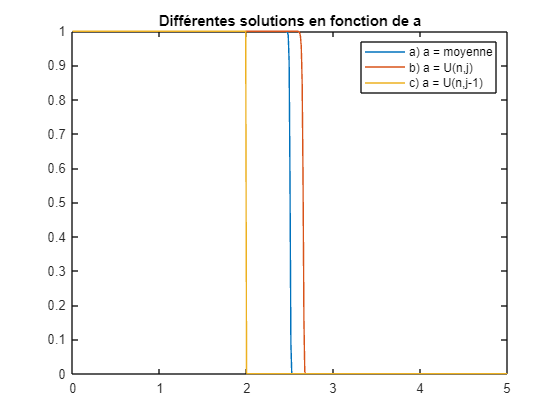

figure
plot(x_grid,sol_a)
hold on
plot(x_grid,sol_b)
hold on
plot(x_grid,sol_c)
legend('a) a = moyenne','b) a = U(n,j)', 'c) a = U(n,j-1)') 
title('Différentes solutions en fonction de a')

xlim([0.00 5.00])
ylim([0.000 1.000])
hold off

Le Schema a (la moyenne) est le seul se deplacant à la bonne vitesse. Le b est en avance alors que le c est en retard.

**Question D**

Dans ce cas la, il se comportera comme le schéma a) (cf calcul fait pendant le TP et en cours/TD, les A=1/2(V+W) représente a=1/2(Uj-Uj-1) ) 

## **Prog 2 :**

### **Solution initiale**

Un = arrayfun(@U02,x_grid);
plot(x_grid, arrayfun(@U0,x_grid))

### Solution numérique :

On va avoir : U(n+1,j) = U(n,j) - (dt/h)*a(n,j)*(U(n,j) - U(n,j-1))

avec a(n,j) = 1/2*(U(n,j) + U(n,j-1)) := sol_moy

for i = 1:ny
    a = 1/2*(Un(1) + 1);
    Un1(1) = Un(1) - dt/h*a*(Un(1) - 1);
    for j = 2:nx
        a = 1/2*(Un(j) + Un(j-1));
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_a2 = Un ;

avec a(n,j) = U(n,j-1) := sol_retro


Un1 = zeros(1,nx);
Un = arrayfun(@U02,x_grid); 

for i = 1:ny
    a = 1;
    Un1(1) = Un(1) - dt/h*a*(Un(1) -1);
    for j = 2:nx
        a = Un(j-1);
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_b2 = Un;

avec a(n,j) = U(n,j) := sol_prez


Un1 = zeros(1,nx);
Un = arrayfun(@U02,x_grid); 

for i = 1:ny
    a = Un(1);
    Un1(1) = Un(1) - dt/h*a*(Un(1) - 1);
    for j = 2:nx
        a = Un(j);
        Un1(j) = Un(j) - dt/h*a*(Un(j) - Un(j-1)); 
    end
    Un = Un1;
end

sol_c2 = Un;

## Solutions exactes : 

Us2 = arrayfun(@U02, mod(x_grid - a*ny*dt - x1,x2 - x1) + x1)

Us2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


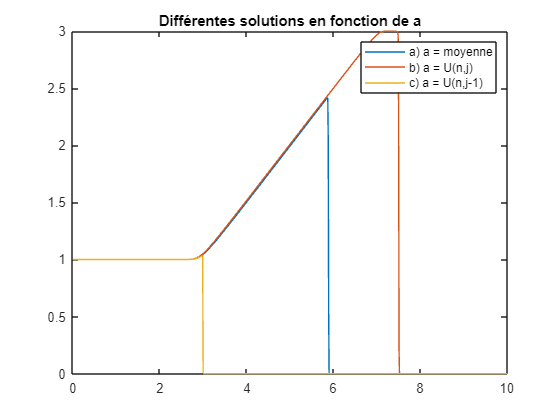

figure
plot(x_grid,sol_a2)
hold on
plot(x_grid,sol_b2)
hold on
plot(x_grid,sol_c2)
legend('a) a = moyenne','b) a = U(n,j)', 'c) a = U(n,j-1)') 
title('Différentes solutions en fonction de a')

De même qu'auparavant seul le shéma a va à la bonne vitesse et nous montre la bonne propagation du choc.